# Stability of Discrete-Time LTI Systems: Solving Exercises in MATLAB

In this live script we illustrate, by examples,  how to use MATLAB  when solving stability and state movement exercises for discrete-time LTI systems.

## Exercise 1: Stability & Equilibrium State Analysis 

Given the LTI system 


$$\left\{ \begin{array}{rcl}
x(n+1) &=& \left[ \begin{array}{cc}
0 & +1 \\-1 & 0
\end{array} \right] x(n) + 
\left[ \begin{array}{c}
-1  \\+1 
\end{array} \right] u(n) \\
y(n) & = & \big[ \begin{array}{cc}
+2 & -2 
\end{array} \big] x(n)
\end{array} \right.$$


**Q1**: 

- Determine the characteristic polynomial of the system and the eigenvalues of the matrix $A$. 

- Using the eigenvalues, what can be state about the stability of the system?

clear
close all
clc
% let's clear the workspace


Let's assign the $A $matrix (we will use the matrices $A\,, B\,, C\, , D$ later)

A = [0, +1;...
     -1, 0];


and compute the characteristic polynomial $p_{A}(\lambda) = \det \big(\lambda I -A \big)$

pA = charpoly(A)

pA =      1     0     1


Please note: $A$ is a numeric matrix, so the command charpoly provides an array with the polynomial coefficients. Indeed, the polynomial is


$$p_{A}(\lambda) = +1\, \lambda^2+0\, \lambda +1 = \lambda^2+1$$


The eigenvalues are the roots of the polynomial $p_{A}(\lambda)$. It is easy to evaluate numerically the roots of a polynomial, given the array of the polynomial coefficients

eigA = roots(pA)

eigA =    0.0000 + 1.0000i
   0.0000 - 1.0000i


The eigenvalues are two complex conjugate values: $\lambda_{A\,,1} = 0+1\, i$, $\lambda_{A\,,2} = 0-1\, i$.

What about the eigenvalues magnitude?

eigMAG = abs(eigA)

eigMAG =      1
     1


Of course, both the eigenvalues have unitary magnitude, and they are distinct eigenvalues. This result allows us to state: **the system is marginally stable**.

What about the state free movement? What are the **response mode matrices**?

Rember, the eigenvalues are all distinct, so we could use the formula


$$A^k =
\sum_{i=1}^n A_{i} 
\lambda_i^k \qquad A_{i} = \lim_{z \to \lambda_i} 
\left [(z-\lambda_i) (zI-A)^{-1} \right ] \; i = 1\,,\;2\,,\; \ldots n$$


or exploiting the left and right eigenvector:


$$A_i = v_i \cdot \tilde v_i^{\top} $$


Unfortunately, due to the complex eigenvalues, we can not evaluate the expressions $A_{i} = \lim_{z \to \lambda_i} 
\left [(z-\lambda_i) (zI-A)^{-1} \right ] \; i = 1\,,\;2\,,\; \ldots n$ using the Symbolic Math Toolbox. In fact, the command `limit` can handle only limits where the limit point is a reeal finite value, or $+\infty$either $-\infty$. Experiment what happens, if you try to use the command `limit `- please uncommment the script row 20 and execute this code section

syms z n
zIA = z*eye(size(A))-A;
zIAinv = inv(zIA);
lambdaA = eig(sym(A));
% A1 = limit((z-lambdaA(1))*zIAinv,z,lambdaA(1))

Using left and right eigenvectors is still possible evaluate the response mode matrices.

[R_eigVects, lambdaSET] = eig(sym(A))

$$R\_eigVects = \left(\begin{array}{cc} \mathrm{i} & -\mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$lambdaSET = \left(\begin{array}{cc} -\mathrm{i} & 0\\ 0 & \mathrm{i} \end{array}\right)$$

% extracting the main diagonal from the square matrix lambdaSET, creating
% a column vector and assigning the col. vector to lambdaSET
lambdaSET = diag(lambdaSET) ;


And for evaluating the left eigenvectors, remeber


$$Q:= [v_1 \, | \, v_2 \, | \cdots | \, v_n] \, \Longrightarrow \,
P = Q^{-1} =
\left [
\begin{array}{c}
\tilde v_1^{\top} \\
\vdots \\
\tilde v_n^{\top}
\end{array}
\right ] ; \,
\tilde v_i^{\top} v_j =
\left \{
\begin{array}{ll}
1 \, \, & i=j \\
0 & i \not= j
\end{array}
\right .$$


Thus

% the left eigenvectors as rows of the inverse matrix, build with the right
% eigenvectors as columns
L_eigVects = inv(R_eigVects) 

$$L\_eigVects = \left(\begin{array}{cc} -\frac{1}{2}\,\mathrm{i} & \frac{1}{2}\\ \frac{1}{2}\,\mathrm{i} & \frac{1}{2} \end{array}\right)$$

Finally, we can compute the response mode matrices, by simply evaluating

A1_mat = R_eigVects(:,1)*L_eigVects(1,:) %#ok<*NASGU> 

$$A1\_mat = \left(\begin{array}{cc} \frac{1}{2} & \frac{1}{2}\,\mathrm{i}\\ -\frac{1}{2}\,\mathrm{i} & \frac{1}{2} \end{array}\right)$$


A2_mat = R_eigVects(:,2)*L_eigVects(2,:)

$$A2\_mat = \left(\begin{array}{cc} \frac{1}{2} & -\frac{1}{2}\,\mathrm{i}\\ \frac{1}{2}\,\mathrm{i} & \frac{1}{2} \end{array}\right)$$

The matrix power $A^n$ is

Apow = A1_mat * lambdaSET(1)^n + A2_mat*lambdaSET(2)^n

$$Apow = \left(\begin{array}{cc} \frac{{\left(-\mathrm{i}\right)}^{n}}{2}+\frac{{\mathrm{i}}^{n}}{2} & \frac{{\left(-\mathrm{i}\right)}^{n}\,\mathrm{i}}{2}-\frac{{\mathrm{i}}^{n}\,\mathrm{i}}{2}\\ -\frac{{\left(-\mathrm{i}\right)}^{n}\,\mathrm{i}}{2}+\frac{{\mathrm{i}}^{n}\,\mathrm{i}}{2} & \frac{{\left(-\mathrm{i}\right)}^{n}}{2}+\frac{{\mathrm{i}}^{n}}{2} \end{array}\right)$$

Please, verify that you obtain the same result for the matrix $A^n$also applying the inverse Z-transform to $z \cdot \big(zI-A \big)^{-1}$.

simplify(expand(Apow))

$$ans = \left(\begin{array}{cc} \frac{{\left(-1\right)}^{n}+1}{2\,{\left(-1\right)}^{n/2}} & -\frac{{\left(-1\right)}^{n}\,\mathrm{i}-\mathrm{i}}{2\,{\left(-1\right)}^{n/2}}\\ \frac{{\left(-1\right)}^{n}\,\mathrm{i}-\mathrm{i}}{2\,{\left(-1\right)}^{n/2}} & \frac{{\left(-1\right)}^{n}+1}{2\,{\left(-1\right)}^{n/2}} \end{array}\right)$$

k = sym("k");
Apow_correct = A^k

$$Apow\_correct = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & \frac{{\mathrm{e}}^{-\frac{\pi \,k\,\mathrm{i}}{2}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{\frac{\pi \,k\,\mathrm{i}}{2}}\,\mathrm{i}}{2}\\ -\frac{{\mathrm{e}}^{-\frac{\pi \,k\,\mathrm{i}}{2}}\,\mathrm{i}}{2}+\frac{{\mathrm{e}}^{\frac{\pi \,k\,\mathrm{i}}{2}}\,\mathrm{i}}{2} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-\frac{\pi \,k\,\mathrm{i}}{2}}}{2}+\frac{{\mathrm{e}}^{\frac{\pi \,k\,\mathrm{i}}{2}}}{2} \end{array}$$


$$V^{-1} * A * V = J \Rightarrow A = V * J * V^{-1} \Rightarrow A^{k} = V * J^{k} * V^{-1}$$


[V, J] = jordan(A);
isequal(inv(V) * A * V, J)

ans = logical
   1



A_sym = sym(A);
modes = V * A_sym^k * inv(V)

$$modes = \begin{array}{l} \left(\begin{array}{cc} \sigma_{2} & \sigma_{1}\\ \sigma_{1} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{{\mathrm{e}}^{-\frac{\pi \,k\,\mathrm{i}}{2}}}{2}+\frac{{\mathrm{e}}^{\frac{\pi \,k\,\mathrm{i}}{2}}}{2}\\ \sigma_{2}=\frac{{\mathrm{e}}^{-\frac{\pi \,k\,\mathrm{i}}{2}}}{2}+\frac{{\mathrm{e}}^{\frac{\pi \,k\,\mathrm{i}}{2}}}{2} \end{array}$$

for i=0:10
    if i==0
        fprintf(1, "a = b \t b = c \t a = c")
    end
    a = subs(Apow, n, i);
    b = subs(modes, k, i);
    c = subs(Apow_correct, k, i);
    a_b = isequal(a,b);
    b_c = isequal(c,b);
    a_c = isequal(a,c);
    fprintf(1, "%d \t %d \t %d\n", a_b, b_c, a_c);
end

a = b 	 b = c 	 a = c

1 	 1 	 1
0 	 0 	 1
1 	 1 	 1
0 	 0 	 1
1 	 1 	 1
0 	 0 	 1
1 	 1 	 1
0 	 0 	 1
1 	 1 	 1
0 	 0 	 1
1 	 1 	 1


%return

Consider the same LTI system 


$$\left\{ \begin{array}{rcl}
x(n+1) &=& \left[ \begin{array}{cc}
0 & +1 \\-1 & 0
\end{array} \right] x(n) + 
\left[ \begin{array}{c}
-1  \\+1 
\end{array} \right] u(n) \\
y(n) & = & \big[ \begin{array}{cc}
+2 & -2 
\end{array} \big] x(n)
\end{array} \right.$$


**Q2**:

- verify that $\bar x = \left[ \begin{array}{cc} 0 & 0 \end{array} \right]^{\top}$ is an equilibrium state for the system, when the input $u(n) = \bar u = 0 \quad \forall n \in \mathbb{Z}$ is applied;

- evaluate the state free movement, obtained starting from an initial state $\hat{x}$ such that $\vert\vert \hat{x}-\bar{x} \vert \vert \le \frac{1}{10}$ . Select 10 different initial states $\hat x$, repeat the computation of the state free movement starting from each of them, store each resulting state sequence, and plot all the 10 movements in a 3D figure (with the time instants $n$ as the first coordinate, the state component $x_1$ as the second coordinate, and the state component $x_2$ as the third coordinate). Use different markers, different colours, different line styles and an appropriate description in the graph legend to enable the identification of each individual state movement.

- Assume $T_s = 1$as sampling period, and evaluate the state movement from the initial time instant $t_0 = 0$ to the time instant $t_{\text{stop}} = 50$

clear
close all
clc

A = [0, +1;...
     -1, 0];
B = [-1; ...
     +1];
C = [+2, -2]; 
D = 0;

t_start = 0;
t_stop = 50;
Ts = 1;

sysD = ss(A, B, C, D, Ts);


Let's verify that $\bar x$ is an equilibrium state, when the input $\bar u$ is applied.

Remember, the pair $\bar{x} \,, \; \bar{u}$ corresponds to an equilibrium state and to an equilibrium input if and only if the pair satisfy the algebraic equation


$$\bar x = A \bar x + B \bar u \, \Longleftrightarrow \,
(I-A) \bar x = B \bar u$$


bar_x = [0;0];
bar_u = 0;

res = A*bar_x+B*bar_u

res =      0
     0


So it has been verified!

Generating 10 states $\hat{x}_{(k)} \quad k=1\,, 2\,, \ldots 10$ such that $\vert\vert \hat{x}-\bar{x} \vert \vert \le \frac{1}{10}$, where $\bar x = \left[ \begin{array}{cc} 0 & 0 \end{array} \right]^{\top}$

R = 10; % 10 state vectors
x_hat = zeros(2, R); % preallocate the array
Nhat_found = 0; % actual number of state vectors in the array x_hat
MAX_Nhat = 10;  % the requested number of vectors
maxDIST = 1e-1; % the maximum distance between bar_x and each vector in x_hat

Let us  generate random vectors, test the distance from the null state,  and each time one of them satisfies the *maximum distance from the origin* constraint, we store it. Let us repeat these operations until we have the required 10 vectors.

while (Nhat_found < MAX_Nhat)
    x_hat_candidate = randn(size(bar_x)); % let's generate a random vector
    norm_hatC = norm((x_hat_candidate));  % evaluate the norm of the vector
                                          % it is the distance between
                                          % x_hat and bar_x
    if (norm_hatC <= maxDIST)
        Nhat_found = Nhat_found+1; % found a vector, so store it!
        x_hat(:, Nhat_found) = x_hat_candidate;
        disp('Found a vector x_hat and store it!')
        fprintf(1, 'So far, we found %d x_hat vectors!\n\r', Nhat_found);
    end % if 
end % while

Found a vector x_hat and store it!


So far, we found 1 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 2 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 3 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 4 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 5 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 6 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 7 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 8 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 9 x_hat vectors!



Found a vector x_hat and store it!


So far, we found 10 x_hat vectors!



fprintf(1, 'Done! We have %d x_hat vectors!\n\r', MAX_Nhat);

Done! We have 10 x_hat vectors!




% now we have 10 state vectors to use as initial states

Now we are able to evaluate each free movement

timeSET = (t_start:Ts:t_stop); % the time instants
Nsteps = numel(timeSET); % how many steps?

xMov = zeros(2, Nsteps); % preallocate memory for storing 
                         % the state movement corresponding to one state
                         % evolution
XmovsSET = cell(1, MAX_Nhat); % a cell array to store the state trajectories

% --- let's evaluate each state movement ---
for i=1:MAX_Nhat
    startX = x_hat(:, i); % select the i-th x_hat state as initial state
    [Y, ~, X] = initial(sysD, startX, timeSET); % evaluation of 
                                                % the state and output
                                                % free movement
    xMov = X'; % store the state evolution
    XmovsSET{i} = xMov; % put it in the cell array
end % for i

Having the state movements, it is possible to plot the results

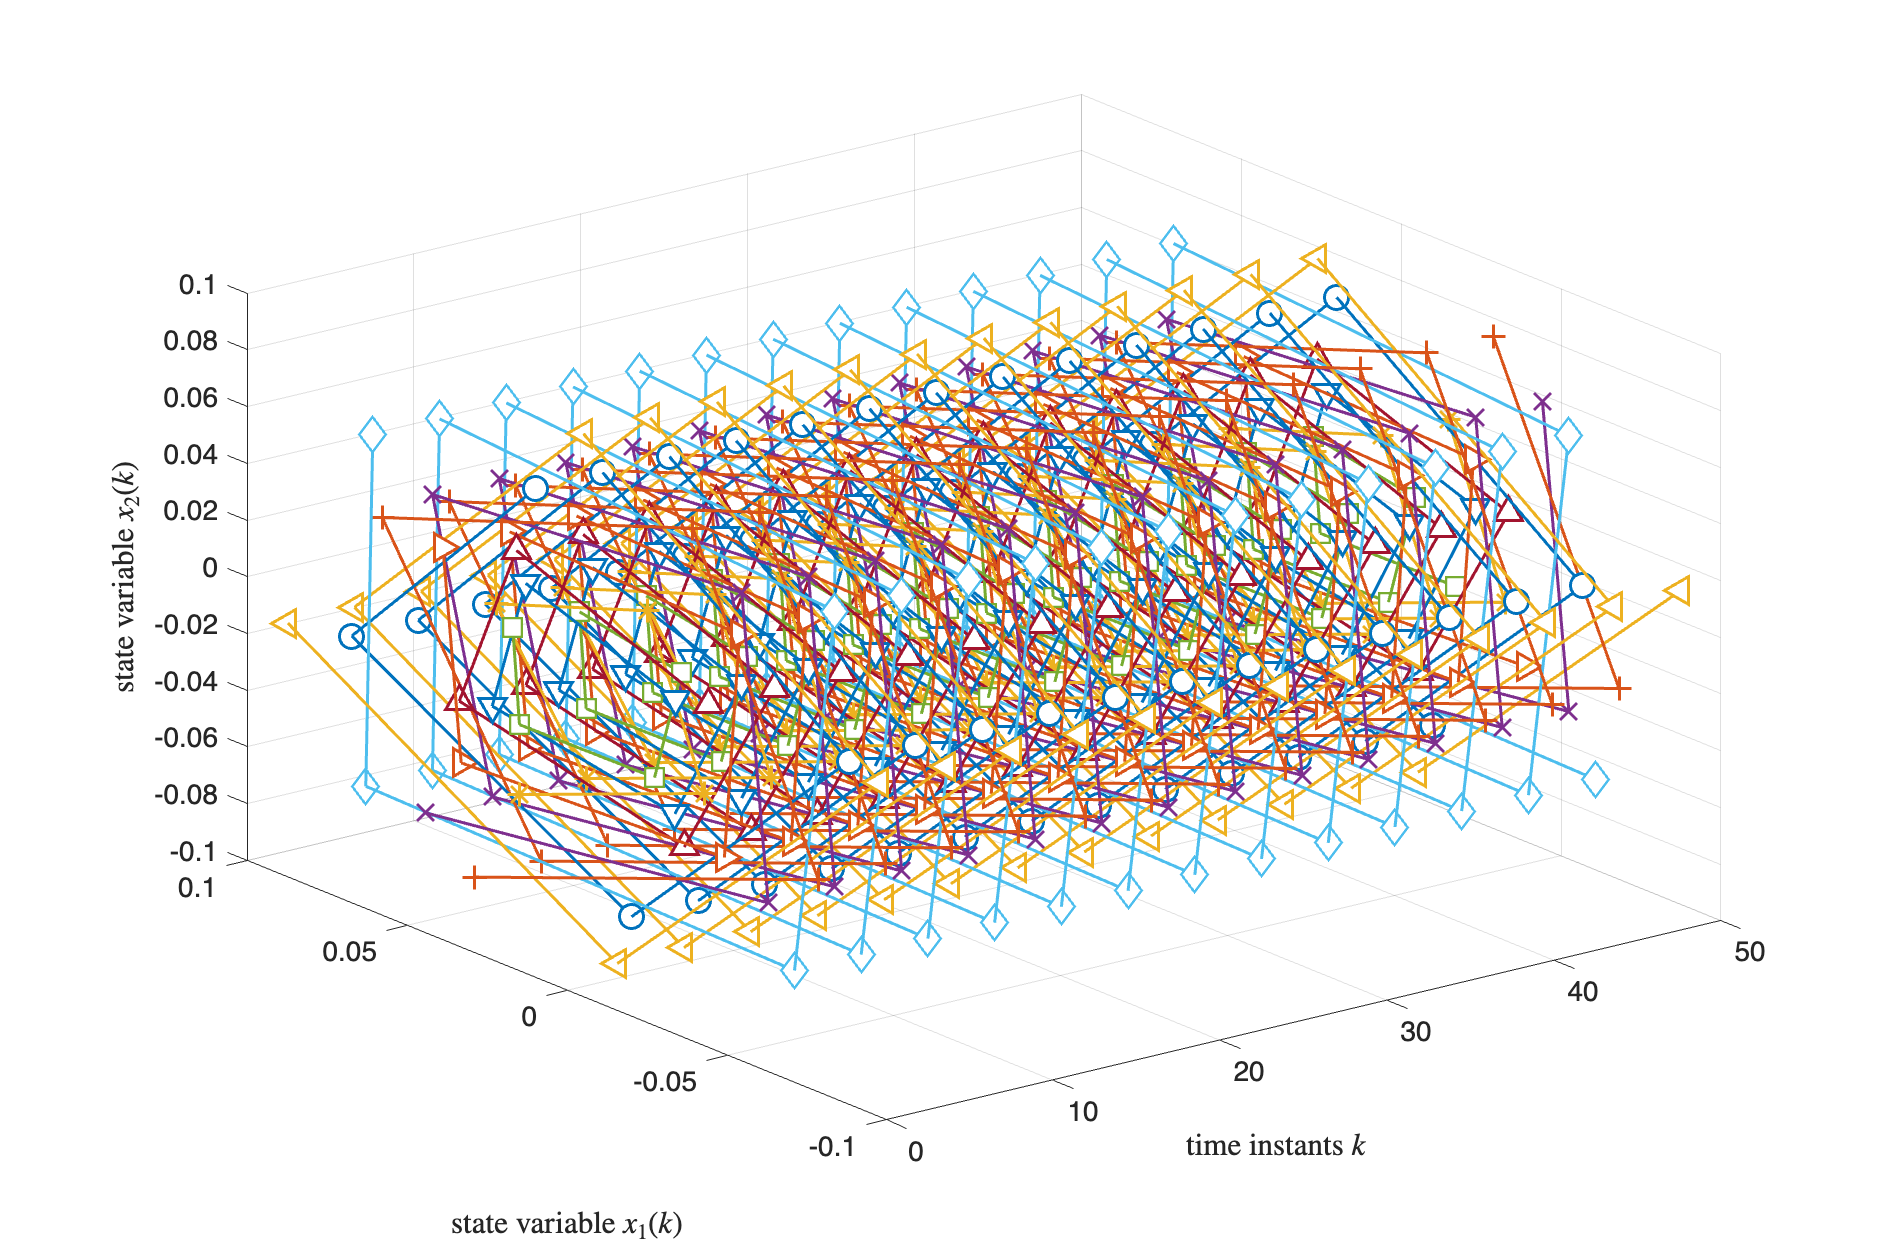

markerSET = {'o', '+', '*', 'x', 'square', 'diamond', ...
              '^', 'v', '>', '<'}; % storing the symbols of different markers

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.9]);

for p = 1:MAX_Nhat
    plot3(timeSET, XmovsSET{p}(1,:), XmovsSET{p}(2,:), 'LineWidth', 1.5, ...
           'Marker', markerSET{p}, 'MarkerSize', 12, 'MarkerEdgeColor', 'auto', ...
           'MarkerFaceColor', 'auto');
    hold on
end % for p
hold off;
xlabel('time instants $k$', 'Interpreter','latex');
ylabel('state variable $x_1(k)$', 'Interpreter','latex');
zlabel('state variable $x_2(k)$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 14);